## 薄板样条方法

1、输入原始控制点坐标及变换后控制点坐标：

original_control=[101,33;102,51;97,42;104,42;
    101,73;100,93;96,83;103,84;
    95,62;126,51;126,74;
    143,45;143,78;137,60;147,60;
    50,65;107,20;99,110;148,28;143,105;171,64]

original_control =    101    33
   102    51
    97    42
   104    42
   101    73
   100    93
    96    83
   103    84
    95    62
   126    51


new_control = [90,39;91,60;84,50;94,49;
    90,81;89,104;83,93;92,95;
    81,71;116,61;115,83;
    135,57;134,86;128,72;139,72;
    36,67;98,23;89,115;136,36;133,107;160,73]

new_control =     90    39
    91    60
    84    50
    94    49
    90    81
    89   104
    83    93
    92    95
    81    71
   116    61


2、读入图片：

testImg = imread('../test_images/B_tps.jpg');
testImg = double(testImg)/256;

3、将图片、控制点输入thin_plate_spline函数，得到结果：

   176

   136



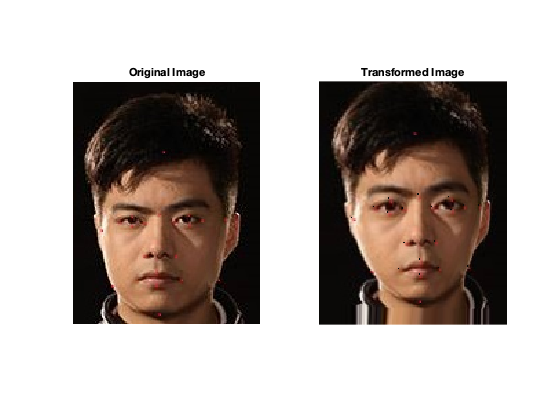

thin_plate_spline(new_control, original_control, testImg);